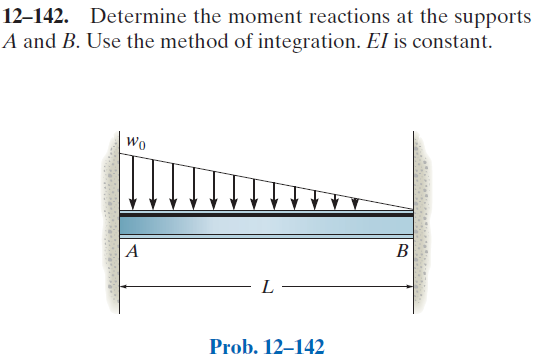

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-142RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-142RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo');
L = sym('L', 'positive');
w1 = findpoly(1, 'thru', [0 -wo], [L 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('reaction', 'force', 'Rb', L);
b = b.add('reaction', 'moment', 'Mb', L);
b = b.add('distributed', 'force', w1, [0 L]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = -\frac{\mathrm{wo}\,x^{2}\,{\left(L-x\right)}^{2}\,\left(3\,L-x\right)}{120\,\text{E}\,\text{I}\,L}$$

dy

$$dy(x) = -\frac{\mathrm{wo}\,x\,\left(L-x\right)\,\left(6\,L^{2}-15\,L\,x+5\,x^{2}\right)}{120\,\text{E}\,\text{I}\,L}$$

m

$$m(x) = -\frac{\mathrm{wo}\,\left(3\,L^{3}-21\,L^{2}\,x+30\,L\,x^{2}-10\,x^{3}\right)}{60\,L}$$

v

$$v(x) = \frac{\mathrm{wo}\,\left(7\,L^{2}-20\,L\,x+10\,x^{2}\right)}{20\,L}$$

w

$$w(x) = -\frac{\mathrm{wo}\,\left(L-x\right)}{L}$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & \frac{L^{2}\,\mathrm{wo}}{20}\\ \mathrm{Mb} & -\frac{L^{2}\,\mathrm{wo}}{30}\\ \mathrm{Ra} & \frac{7\,L\,\mathrm{wo}}{20}\\ \mathrm{Rb} & \frac{3\,L\,\mathrm{wo}}{20} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

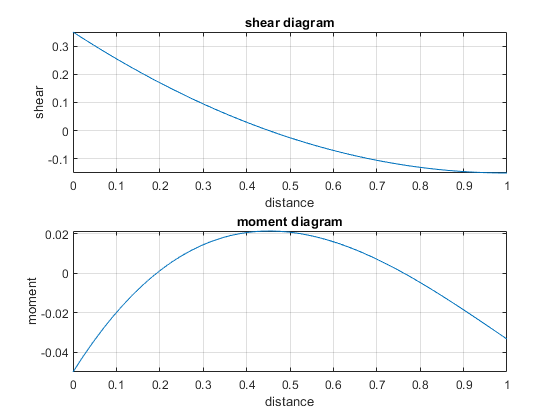

beam.shear_moment(m, v, [0 1], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;